车轮直径：0.55m

车体质量：135kg

人：70kg

阻力：可以定一个常数

力矩：3.0Nm

减速器：30：1，15：1

转换速度18km/h

a=(tau/r=F_go)/m-F_drag

m_car=130;
m_per=70;
tau=90;
d=0.55;
r=d/2;
F_go=tau/r

F_go = 327.2727

a=F_go/(m_car+m_per)/1.4

a = 1.1688

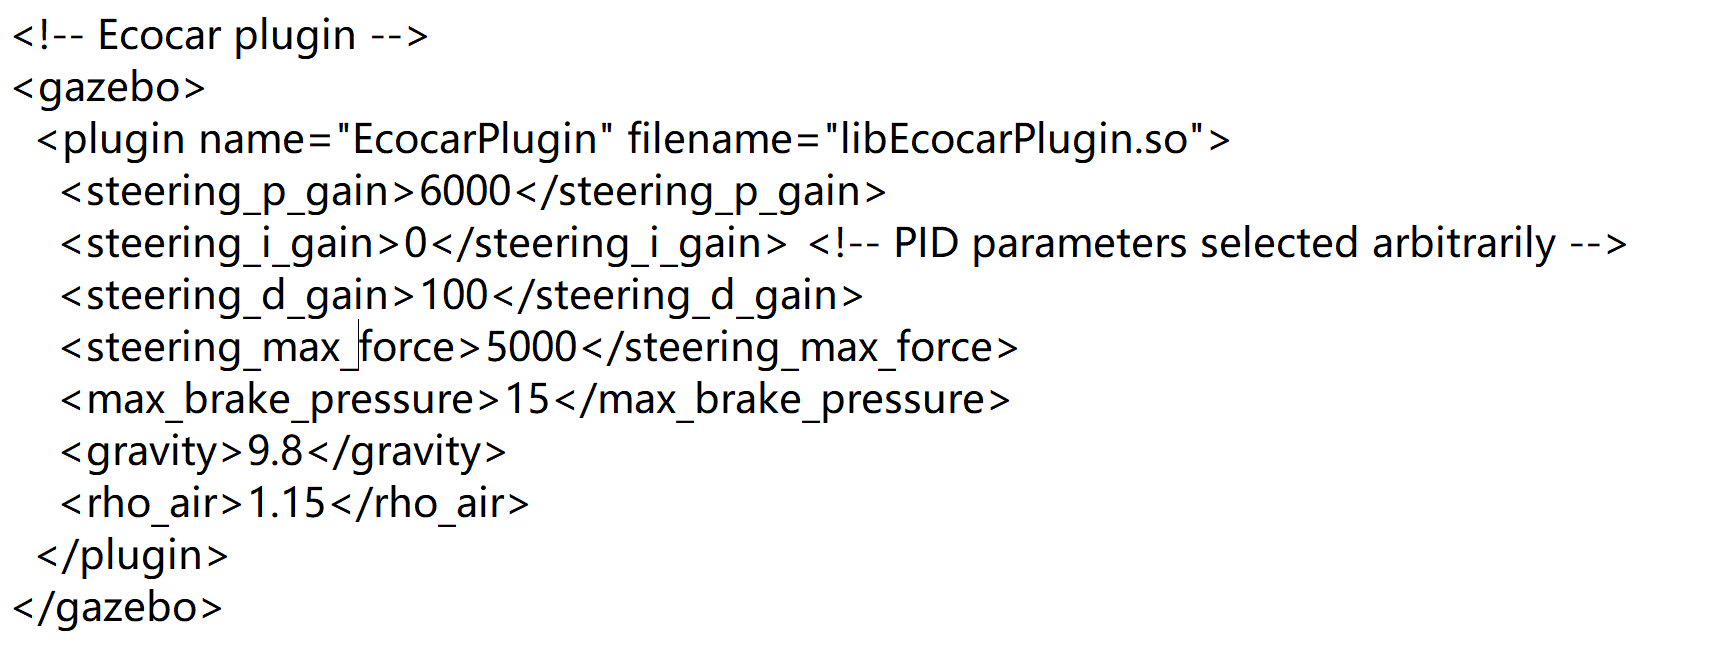

//const double A_front = 0.8575;

//const double Cd = 0.1874;

math::Vector3 dragForce = -0.5 * rho_air * A_front * Cd * linearVel.GetSquaredLength() * linearVelNormalized;

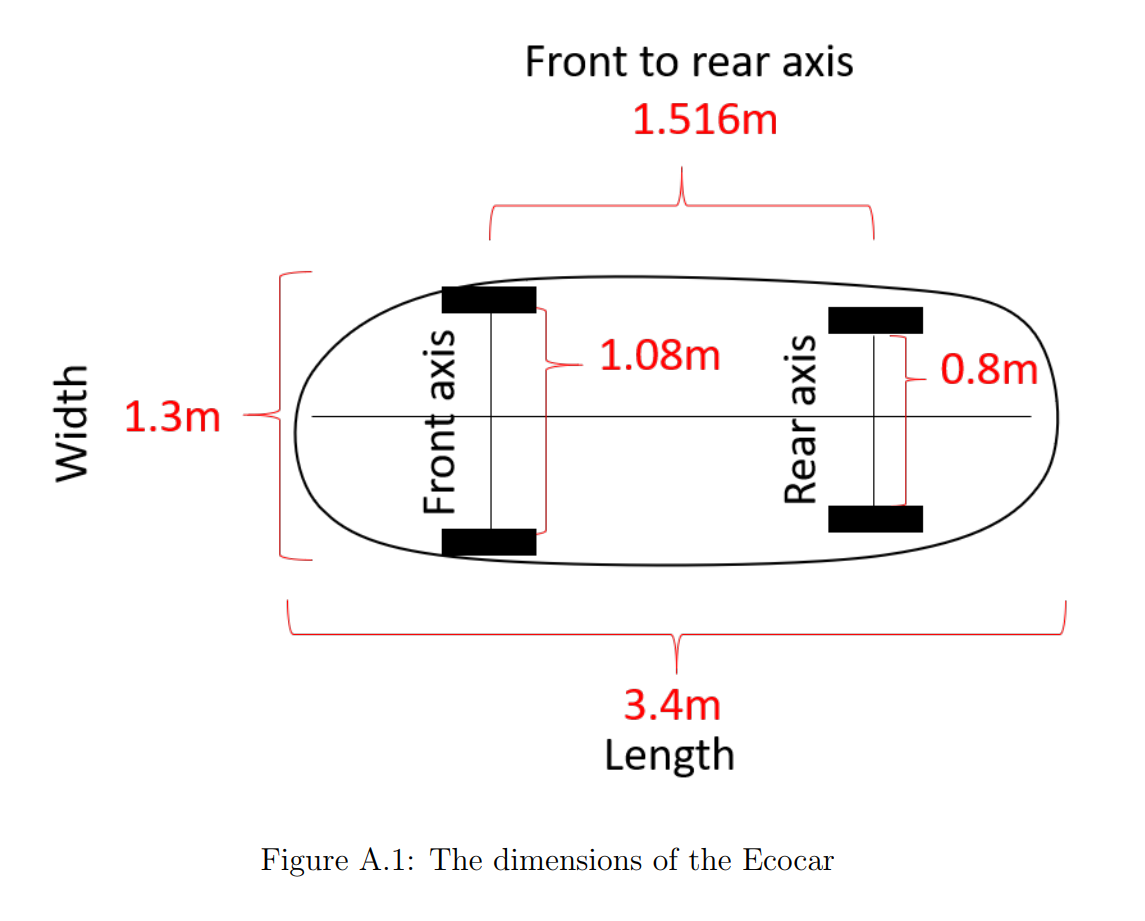

As can be seen in figure 10.15 the speed is between 25 and 24 kmph during the turn.

The turn signal is given at t=22.8s and the smooth and stable steering output can be

seen in figure 10.16, showing the stable steering output throughout the turn. From this it

can be seen that it is possible for the car to clear a 90-degree turn with turn radius 7.5m

at 25kmph, however the high speed pushes the car right from the middle of the road and

closer to the right hand barrier. This can be a problem after the turn as the reason for

driving in the middle of the road is to have as much steering margin as possible.  

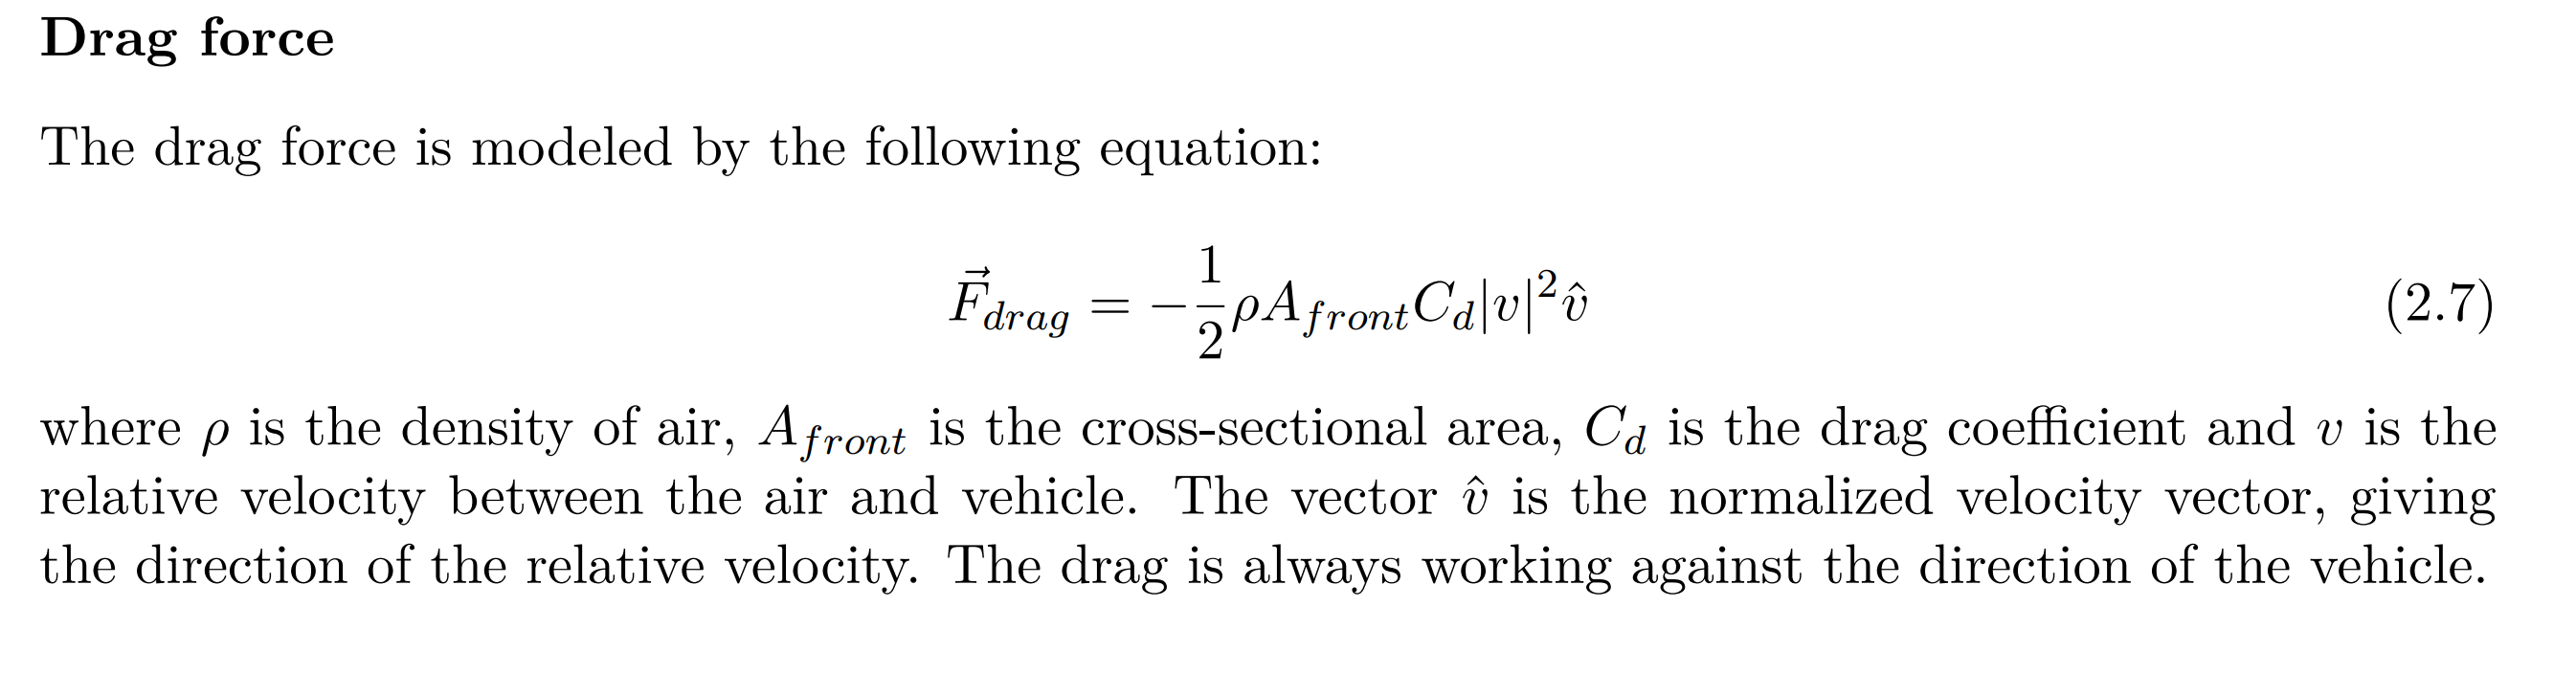

A_front = 0.8575;
Cd = 1.0;
rho_air=1.15;
g=9.8

g = 9.8000

F_drag=-0.5*A_front*Cd*rho_air*36

F_drag = -17.7502

a_drag=F_drag/130

a_drag = -0.1365

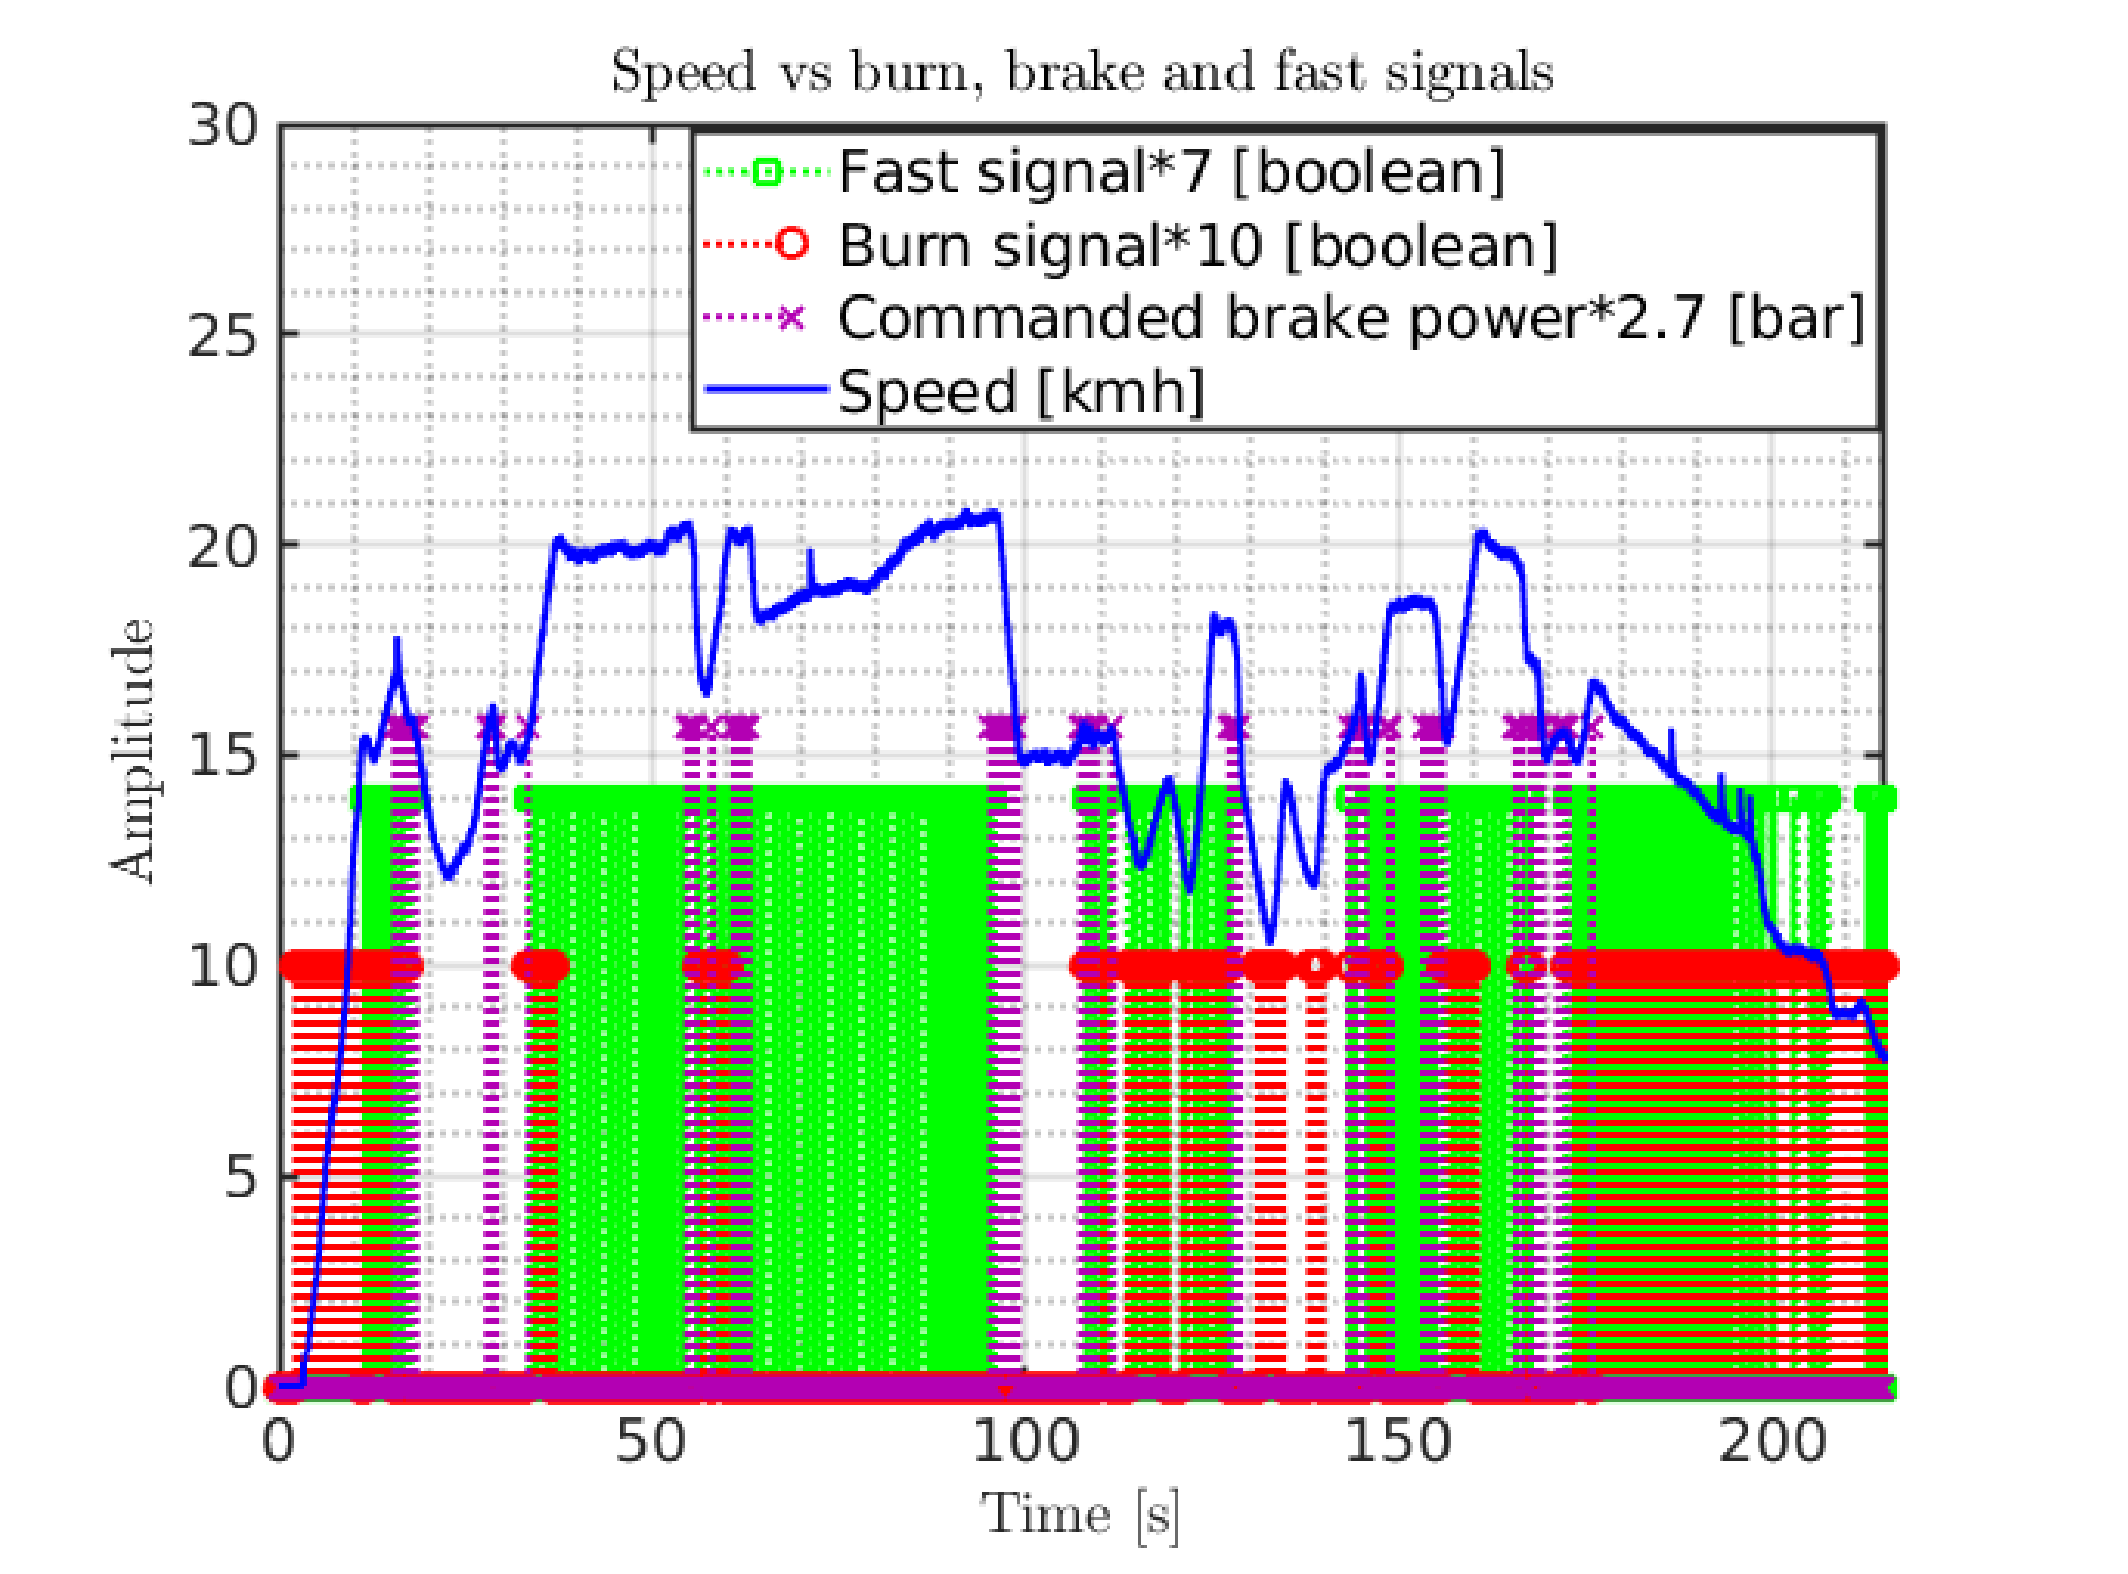

In figure 11.1 the speed control throughout the lap can be seen. The amplitudes of burn

and brake signals are amplified for visual purposes. Braking is only done when either

switching from fast to slow speeds, or if the car is coasting downhill and accelerating

above the maxspeed, whether fast or slow. It should be noted that throughout the lap

the speed measurements are seen to occasionally spike. These spikes take 200ms to settle.

Furthermore, at t=12s a switch from 1st to 2nd gear can be seen. In 2nd gear the car

accelerates significantly slower.  

a_1_gear=15/3.6/8

a_1_gear = 0.5208

a_2_gear=3/3.6/3

a_2_gear = 0.2778

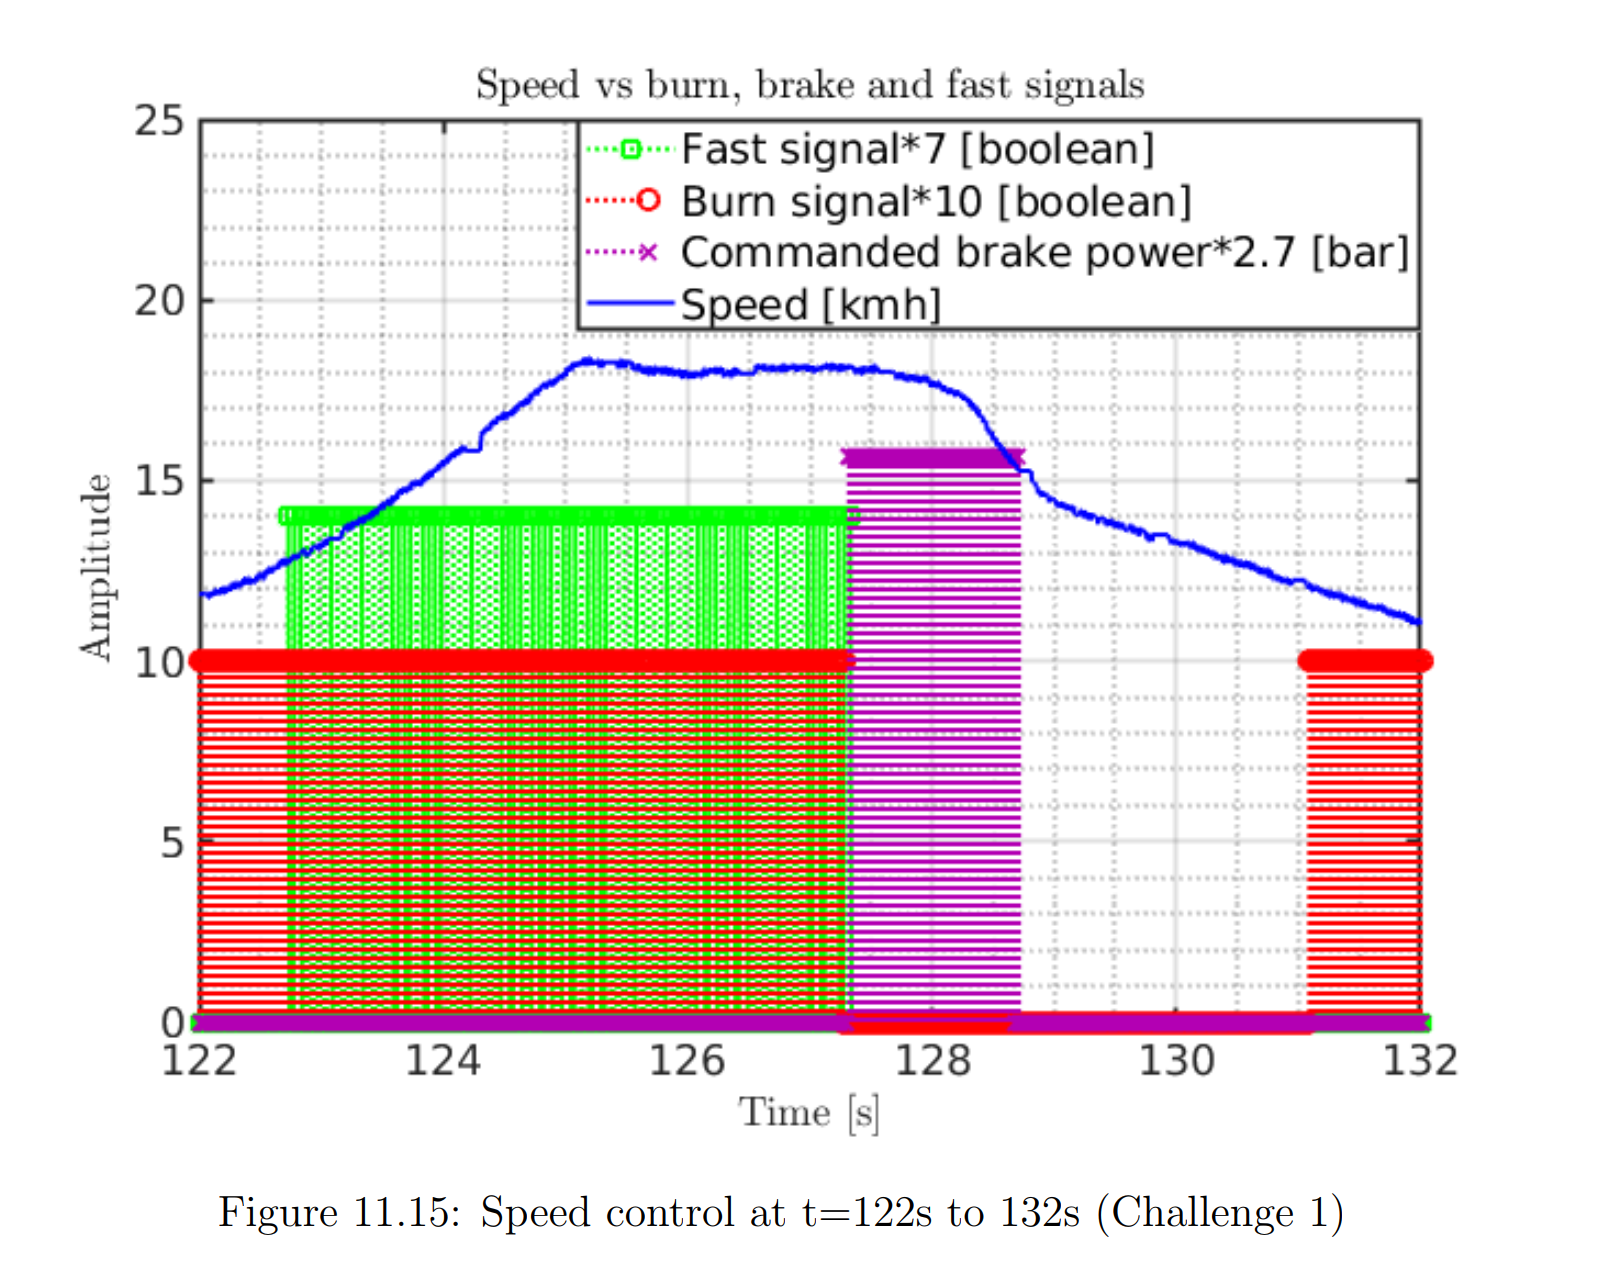

Another thing to note is that at t=125s the electronic system switches to 2nd gear

while still driving uphill, resulting in the inability to accelerate up to 20kmph.  

a_1_gear_test=6/3.6/3

a_1_gear_test = 0.5556